`Erfan Panahi   810198369`

## Communication Systems I

# Computer Assignement 3

## ***Contents:***

***    Part 1 . Transmitter***

- `Phase Modulation`

- `Frequency Modulation`

***    Part 2 . Receiver***

- `Phase Modulation`

- `Frequency Modulation`

***    Part 3 . Single Tone Modulation***

# ` Part 1. ``Transmitter`

##     `* `***Phase Modulation:***

`Definition of `$m\left(t\right)$`:`

clear;
fs = 10e3;
t = 0:1/fs:10;
m = sin(pi*t);
fc = 100;
Ac = 1;

`PM (`$\phi_{\Delta } =10$`):`

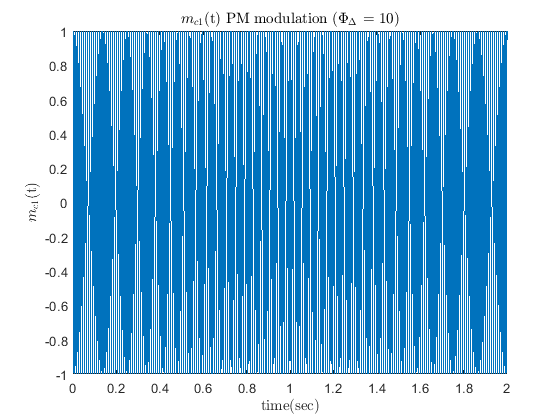

phasedev1 = 10;
mc1_pm = pm(m,Ac,phasedev1,fc,t);
plot(t,mc1_pm);
xlim([0 2]);
title('$m_{c1}$(t) PM modulation ($\Phi_\Delta$ = 10)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c1}$(t)','Interpreter','latex');

`NBPM (`$\phi_{\Delta } =10$`):`

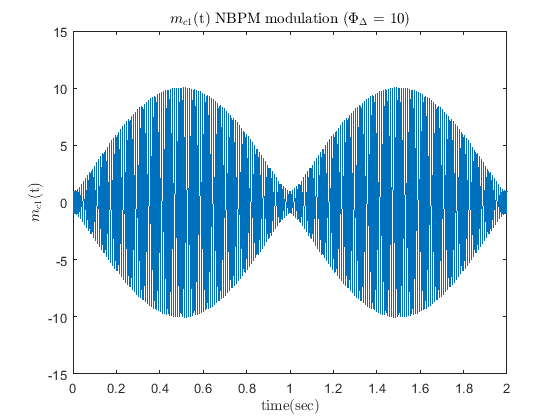

mc1_nbpm = nbpm(m,Ac,phasedev1,fc,t);
plot(t,mc1_nbpm);
xlim([0 2]);
title('$m_{c1}$(t) NBPM modulation ($\Phi_\Delta$ = 10)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c1}$(t)','Interpreter','latex');

`Mean squared error (`$\phi_{\Delta } =10$`):`

error_part3 = immse(mc1_pm,mc1_nbpm)

error_part3 = 25.8110

`PM (`$\phi_{\Delta } =0\ldotp 01$`):`

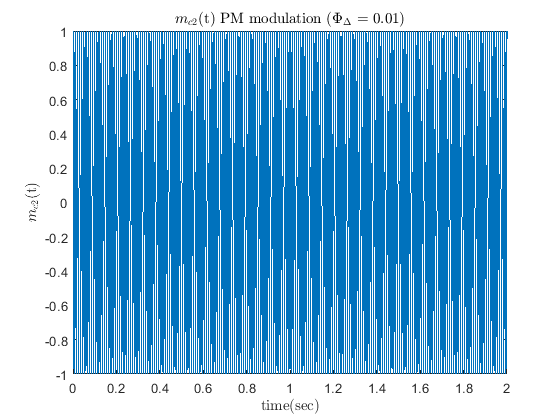

phasedev2 = 0.01;
mc2_pm = pm(m,Ac,phasedev2,fc,t);
plot(t,mc2_pm);
xlim([0 2]);
title('$m_{c2}$(t) PM modulation ($\Phi_\Delta$ = 0.01)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c2}$(t)','Interpreter','latex');

`NBPM (`$\phi_{\Delta } =0\ldotp 01$`):`

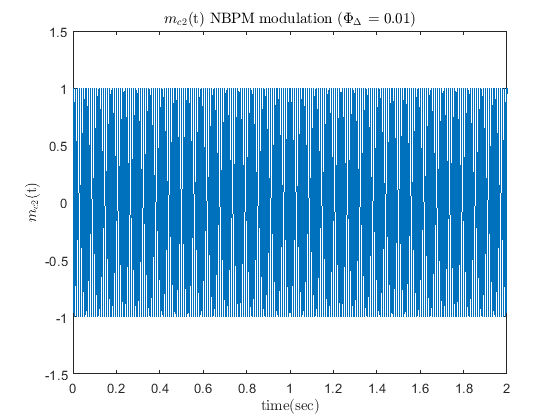

mc2_nbpm = nbpm(m,Ac,phasedev2,fc,t);
plot(t,mc2_nbpm);
xlim([0 2]);
title('$m_{c2}$(t) NBPM modulation ($\Phi_\Delta$ = 0.01)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c2}$(t)','Interpreter','latex');

`Mean squared error (`$\phi_{\Delta } =0\ldotp 01$`):`

error_part4 = immse(mc2_pm,mc2_nbpm)

error_part4 = 4.6874e-10

$m_c \left(t\right)$ `using` `pmmod:`

[`y = pmmod(x,Fc,Fs,phasedev)`](https://www.mathworks.com/help/comm/ref/pmmod.html#d123e66456)` modulates the message signal x using phase modulation.`


$$\phi_{\Delta } =10$$


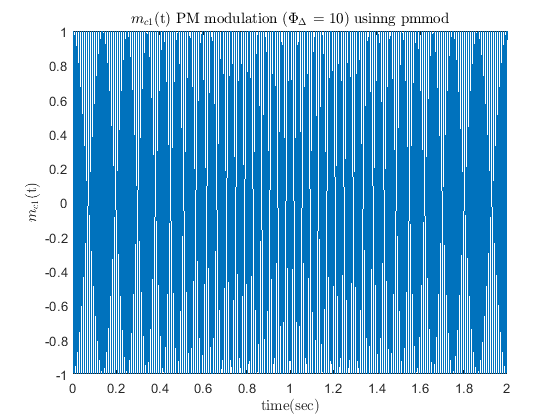

mc1_pmmod=pmmod(m,fc,fs,phasedev1);
plot(t,mc1_pmmod);
xlim([0 2]);
title('$m_{c1}$(t) PM modulation ($\Phi_\Delta$ = 10) usinng pmmod','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c1}$(t)','Interpreter','latex');


$$\phi_{\Delta } =0\ldotp 01$$


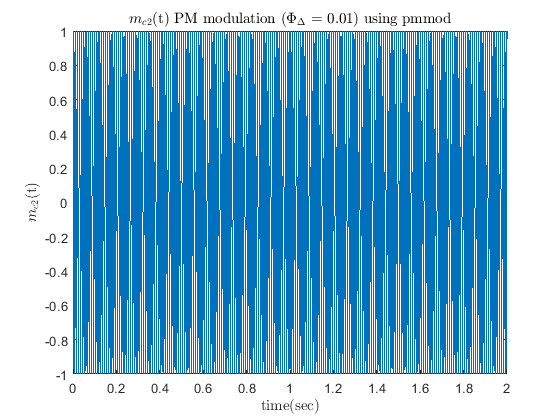

mc2_pmmod=pmmod(m,fc,fs,phasedev2);
plot(t,mc2_pmmod);
xlim([0 2]);
title('$m_{c2}$(t) PM modulation ($\Phi_\Delta$ = 0.01) using pmmod','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c2}$(t)','Interpreter','latex');

`Mean squared error (`$\phi_{\Delta } =10$`) pm and pmmod:`

error_part6 = immse(mc1_pm,mc1_pmmod)

error_part6 = 0

##  `* `***Frequency Modulation:***

`Definition of `$m\left(t\right)$`:`

clear;
fs = 10e3;
t = 0:1/fs:10;
m = sin(pi*t);
fc = 100;
Ac = 1;

`FM (`$f_{\Delta } =10$`):`

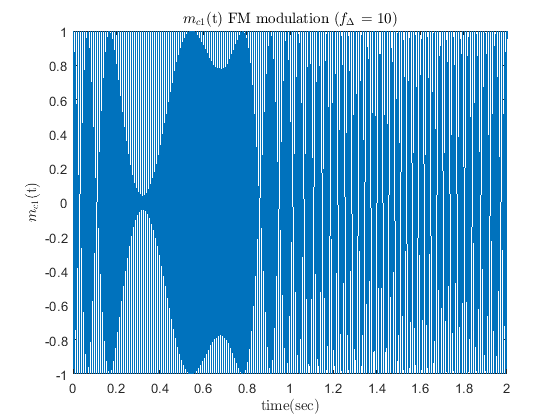

freqdev1 = 10;
mc1_fm = fm(m,Ac,freqdev1,fc,t);
plot(t,mc1_fm);
xlim([0 2]);
title('$m_{c1}$(t) FM modulation ($f_\Delta$ = 10)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c1}$(t)','Interpreter','latex');

`NBFM (`$f_{\Delta } =10$`):`

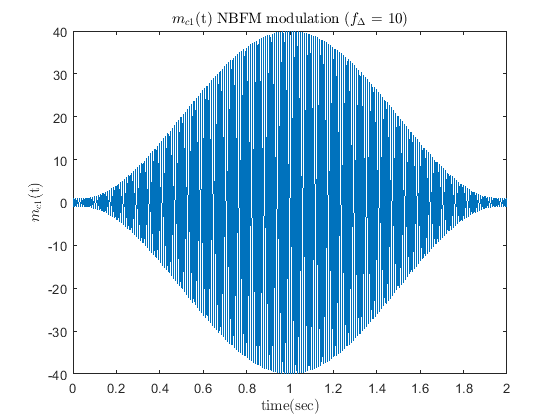

mc1_nbfm = nbfm(m,Ac,freqdev1,fc,t);
plot(t,mc1_nbfm);
xlim([0 2]);
title('$m_{c1}$(t) NBFM modulation ($f_\Delta$ = 10)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c1}$(t)','Interpreter','latex');

`Mean squared error (`$f_{\Delta } =10$`):`

error_part8 = immse(mc1_fm,mc1_nbfm)

error_part8 = 297.3337

`FM (`$f_{\Delta } =0\ldotp 01$`):`

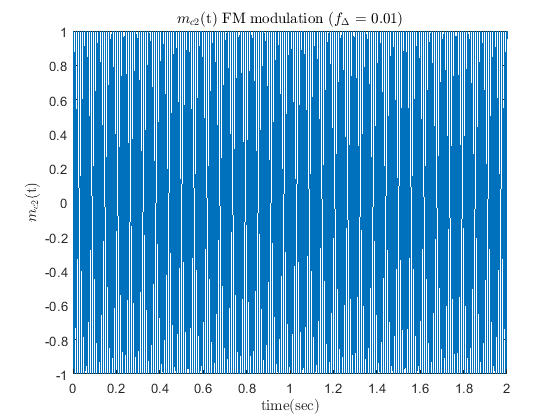

freqdev2 = 0.01;
mc2_fm = fm(m,Ac,freqdev2,fc,t);
plot(t,mc2_fm);
xlim([0 2]);
title('$m_{c2}$(t) FM modulation ($f_\Delta$ = 0.01)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c2}$(t)','Interpreter','latex');

`NBFM (`$f_{\Delta } =0\ldotp 01$`):`

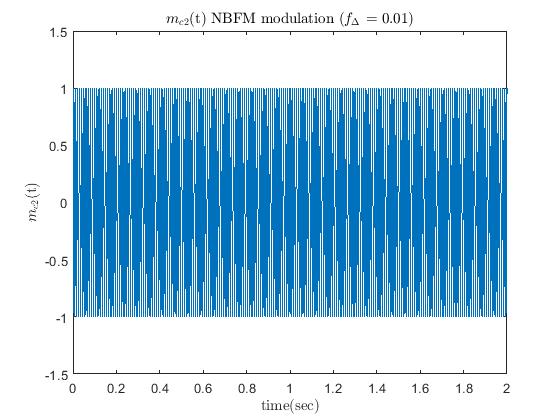

mc2_nbfm = nbfm(m,Ac,freqdev2,fc,t);
plot(t,mc2_nbfm);
xlim([0 2]);
title('$m_{c2}$(t) NBFM modulation ($f_\Delta$ = 0.01)','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c2}$(t)','Interpreter','latex');

`Mean squared error (`$f_{\Delta } =0\ldotp 01$`):`

error_part9 = immse(mc2_fm,mc2_nbfm)

error_part9 = 8.7493e-08

$m_c \left(t\right)$ `using` `pmmod:`

[`y = fmmod(x,Fc,Fs,freqdev)`](https://www.mathworks.com/help/comm/ref/fmmod.html#d123e42265) `returns a frequency modulated (FM) signal y, given the input message signal x, where the carrier signal has frequency Fc and sampling rate Fs. freqdev is the frequency deviation of the modulated signal.`


$$f_{\Delta } =10$$


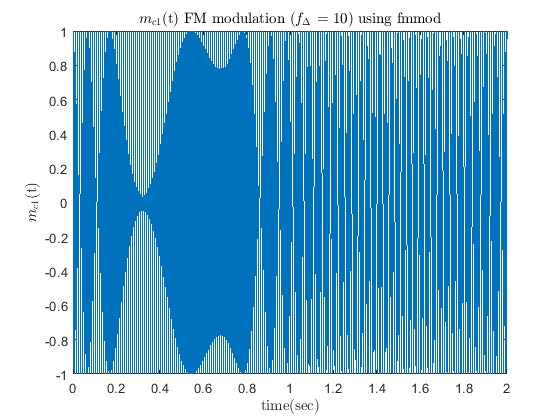

mc1_fmmod=fmmod(m,fc,fs,freqdev1);
plot(t,mc1_fmmod);
xlim([0 2]);
title('$m_{c1}$(t) FM modulation ($f_\Delta$ = 10) using fmmod','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c1}$(t)','Interpreter','latex');


$$f_{\Delta } =0\ldotp 01$$


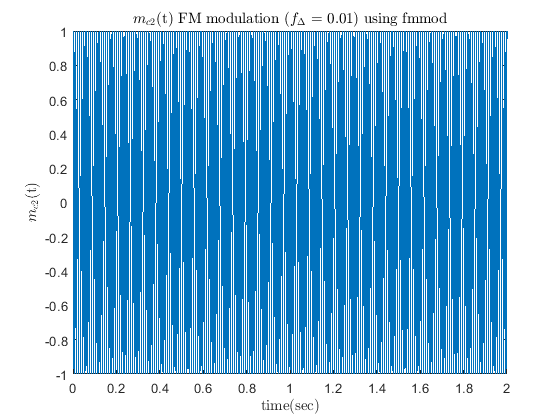

mc2_fmmod=fmmod(m,fc,fs,freqdev2);
plot(t,mc2_fmmod);
xlim([0 2]);
title('$m_{c2}$(t) FM modulation ($f_\Delta$ = 0.01) using fmmod','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('$m_{c2}$(t)','Interpreter','latex');

`Mean squared error (`$f_{\Delta } =10$`):`

error_part11 = immse(mc1_fmmod,mc1_fm)

error_part11 = 2.4674e-06

`Problem 12.`

clear;
fs = 10e3;
t = 0:1/fs:10;
m = sin(pi*t);
fc = 100;
Ac = 1;

 `* `***Phase Modulation:***

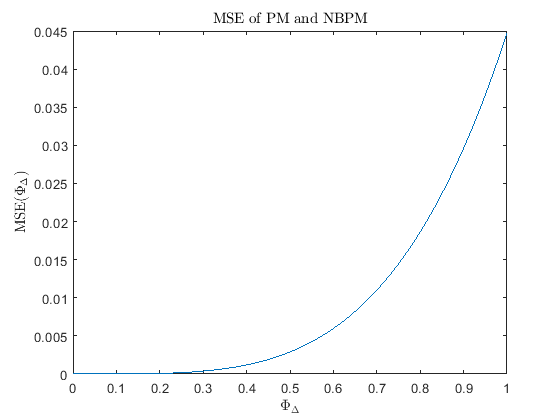

phasedev = 0:0.01:1;
errorPM =zeros(1,length(phasedev));
for i = 1:length(phasedev)
    PM = pm(m,Ac,phasedev(i),fc,t);
    NBPM = nbpm(m,Ac,phasedev(i),fc,t);
    errorPM(i) = immse(PM,NBPM);
    if(errorPM<0.01/max(PM))
        max_phasedev = phasedev(i);
    end
end
plot(phasedev,errorPM);
title('MSE of PM and NBPM','Interpreter','latex');
xlabel('$\Phi_\Delta$','Interpreter','latex');
ylabel('MSE($\Phi_\Delta$)','Interpreter','latex');

`maximum phase deviation:`

 max_phasedev

max_phasedev = 0.6800

 `* `***Frequency Modulation:***

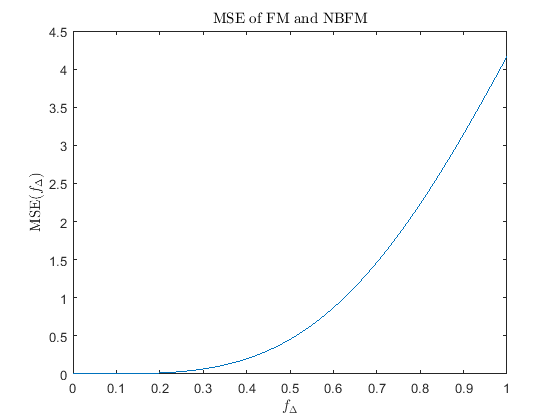

freqdev = 0:0.01:1;
errorFM =zeros(1,length(freqdev));
for i = 1:length(freqdev)
    FM = fm(m,Ac,freqdev(i),fc,t);
    NBFM = nbfm(m,Ac,freqdev(i),fc,t);
    errorFM(i) = immse(FM,NBFM);
     if(errorFM<0.01/max(FM))
        max_freqdev = freqdev(i);
    end
end
plot(freqdev,errorFM);
title('MSE of FM and NBFM','Interpreter','latex');
xlabel('$f_\Delta$','Interpreter','latex');
ylabel('MSE($f_\Delta$)','Interpreter','latex');

`maximum frequency deviation:`

max_freqdev

max_freqdev = 0.1800

# `Part 2. Receiver`

## `    * `***Frequency Modulation:***

`Using fdm:`

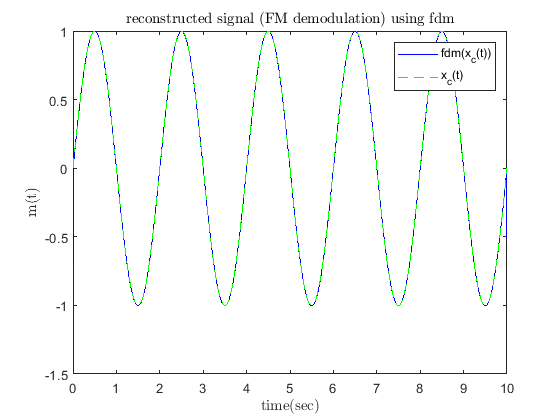

m_fdm = fdm(mc1_fm,Ac,freqdev1,fc,fs);
plot(t,m_fdm,'b',t,m,'g--');
legend('fdm(x_c(t))','x_c(t)');
title('reconstructed signal (FM demodulation) using fdm','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('m(t)','Interpreter','latex');

error_m_fdm = immse(m_fdm,m)

error_m_fdm = 2.0556e-05

`Using fmdemod:`

[`z = fmdemod(y,Fc,Fs,freqdev)`](https://www.mathworks.com/help/comm/ref/fmdemod.html#d123e41945)` returns a demodulated signal z, given the input frequency modulated (FM) signal y, where the carrier signal has frequency Fc and sampling rate Fs. freqdev is the frequency deviation of the modulated signal.`

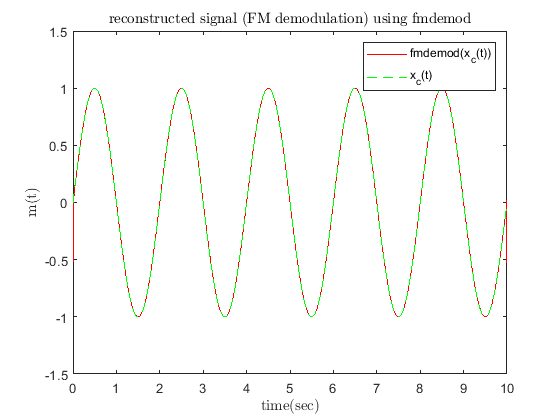

m_fmdemod = fmdemod(Ac*mc1_fm,fc,fs,freqdev1);
plot(t,m_fmdemod,'r',t,m,'g--');
legend('fmdemod(x_c(t))','x_c(t)');
title('reconstructed signal (FM demodulation) using fmdemod','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('m(t)','Interpreter','latex');

error_m_fmdemod = immse(m_fmdemod,m)

error_m_fmdemod = 2.4878e-05

error_fdm_fmdemod = immse(m_fmdemod,m_fdm)

error_fdm_fmdemod = 1.4634e-05

##     `* `***Phase Modulation:***

`Using pdm:`

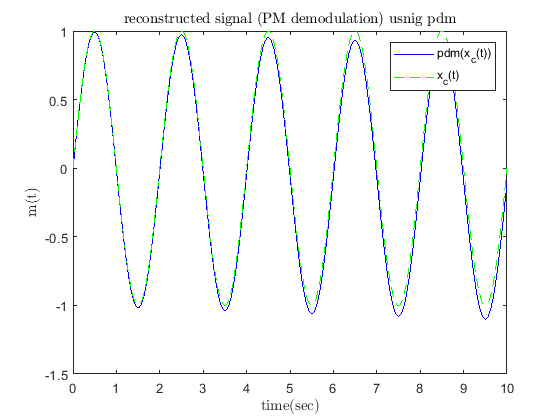

m_pdm = pdm(mc1_pm,Ac,phasedev1,fc,fs,t);
plot(t,m_pdm,'b',t,m,'g--');
legend('pdm(x_c(t))','x_c(t)');
title('reconstructed signal (PM demodulation) usnig pdm','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('m(t)','Interpreter','latex');

error_m_pdm = immse(m_pdm,m)

error_m_pdm = 0.0037

`Using pmdemod:`

[`z = pmdemod(y,Fc,Fs,phasedev)`](https://www.mathworks.com/help/comm/ref/fmdemod.html#d123e41945)` demodulates the phase-modulated signal y at the carrier frequency Fc (hertz). z and the carrier signal have sampling rate Fs (hertz), where Fs must be at least 2*Fc. The phasedev argument is the phase deviation of the modulated signal, in radians.`

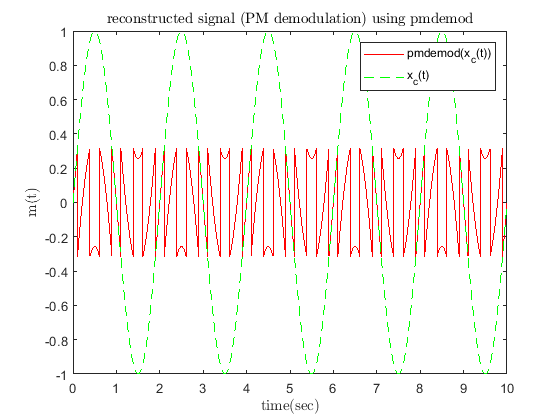

m_pmdemod = pmdemod(Ac*mc1_pm,fc,fs,phasedev1);
plot(t,m_pmdemod,'r',t,m,'g--');
legend('pmdemod(x_c(t))','x_c(t)');
title('reconstructed signal (PM demodulation) using pmdemod','Interpreter','latex');
xlabel('time(sec)','Interpreter','latex');
ylabel('m(t)','Interpreter','latex');

error_m_pmdemod = immse(m_pmdemod,m)

error_m_pmdemod = 0.5713

error_pdm_pmdemod = immse(m_pmdemod,m_pdm)

error_pdm_pmdemod = 0.5812

# `Part 3. Single tone modulation`

`Definition of `$m\left(t\right)$`:`

clear;
fs = 10e3;
t = 0:1/fs:1;
f=-fs/2:fs/length(t):(fs-1)/2;
f_m = 10;
m = sin(2*pi*f_m*t);
fc = 100;
Ac = 1;

## `    * Phase`*** Modulation:***

`Using fpmm:`

- 
$$\beta =0\ldotp 1:$$


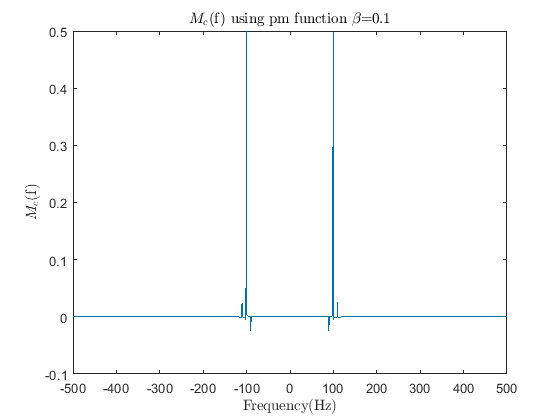

beta1 = 0.1;
mc1_pm_t = pm(m,Ac,beta1,fc,t);
mc1_pm_f = fftshift(fft(mc1_pm_t))/length(mc1_pm_t);
plot(f,real(mc1_pm_f));
xlim([-500 500]);
title('$M_c$(f) using pm function $\beta$=0.1','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');

- 
$$\beta =1:$$


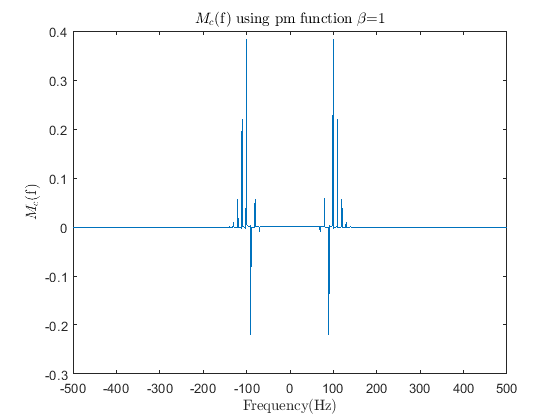

beta2 = 1;
mc2_pm_t = pm(m,Ac,beta2,fc,t);
mc2_pm_f = fftshift(fft(mc2_pm_t))/length(mc2_pm_t);
plot(f,real(mc2_pm_f));
xlim([-500 500]);
title('$M_c$(f) using pm function $\beta$=1','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');

- 
$$\beta =10:$$


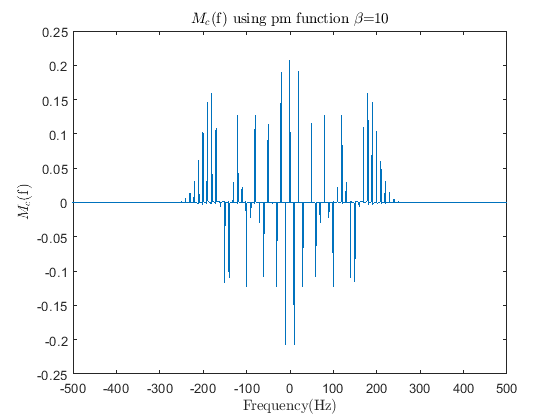

beta3 = 10;
mc3_pm_t = pm(m,Ac,beta3,fc,t);
mc3_pm_f = fftshift(fft(mc3_pm_t))/length(mc3_pm_t);
plot(f,real(mc3_pm_f));
xlim([-500 500]);
title('$M_c$(f) using pm function $\beta$=10','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');

`Using bessel expansion:`

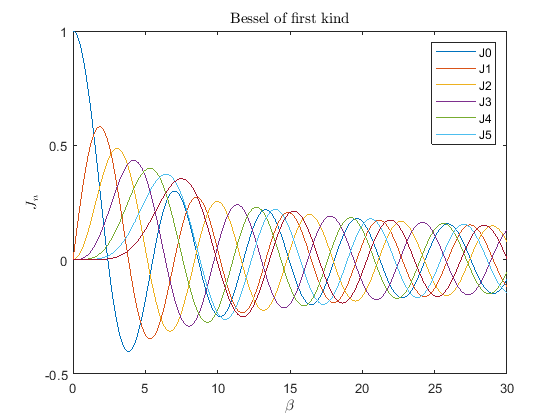

beta = 0:0.1:30;
J = zeros(6,301);
for i = 0:6
    J(i+1,:)=besselj(i,beta);
end
plot(beta,J);
legend('J0','J1','J2','J3','J4','J5');
title('Bessel of first kind','Interpreter','latex');
xlabel('$\beta$','Interpreter','latex');
ylabel('$J_n$','Interpreter','latex');

n = 0:25;


$$\beta =0\ldotp 1:$$


Jn01 = besselj(n,beta1);
for i = n
    if (i == 0)
        fprintf('Jn for Beta=0.1 (0<n<25\n');
    end
    fprintf('n = %d : %.4f\n',i,Jn01(i+1));
end

Jn for Beta=0.1 (0<n<25


n = 0 : 0.9975
n = 1 : 0.0499
n = 2 : 0.0012
n = 3 : 0.0000
n = 4 : 0.0000
n = 5 : 0.0000
n = 6 : 0.0000
n = 7 : 0.0000
n = 8 : 0.0000
n = 9 : 0.0000
n = 10 : 0.0000
n = 11 : 0.0000
n = 12 : 0.0000
n = 13 : 0.0000
n = 14 : 0.0000
n = 15 : 0.0000
n = 16 : 0.0000
n = 17 : 0.0000
n = 18 : 0.0000
n = 19 : 0.0000
n = 20 : 0.0000
n = 21 : 0.0000
n = 22 : 0.0000
n = 23 : 0.0000
n = 24 : 0.0000
n = 25 : 0.0000


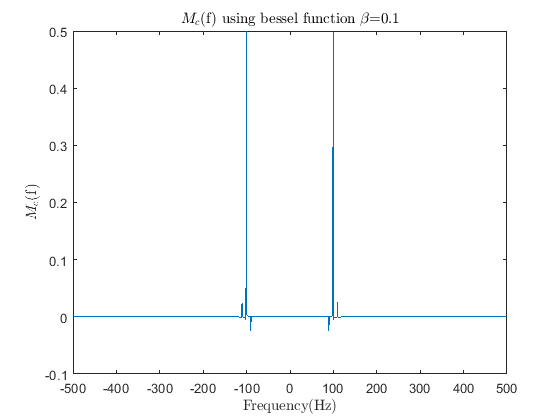

N1 = 2;
mc1_bessel_t = zeros(1,length(t));
for i = -N1:N1
    mc1_bessel_t = mc1_bessel_t + Ac*besselj(i,beta1)*cos(2*pi*(fc+i*f_m)*t); 
end
mc1_bessel_f = fftshift(fft(mc1_bessel_t))/length(mc1_bessel_t);
plot(f,real(mc1_bessel_f));
xlim([-500 500]);
title('$M_c$(f) using bessel function $\beta$=0.1','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');


$$\beta =1:$$


Jn1 = besselj(n,beta2);
for i = n
    if (i == 0)
        fprintf('Jn for Beta=1 (0<n<25\n');
    end
    fprintf('n = %d : %.4f\n',i,Jn1(i+1));
end

Jn for Beta=1 (0<n<25


n = 0 : 0.7652
n = 1 : 0.4401
n = 2 : 0.1149
n = 3 : 0.0196
n = 4 : 0.0025
n = 5 : 0.0002
n = 6 : 0.0000
n = 7 : 0.0000
n = 8 : 0.0000
n = 9 : 0.0000
n = 10 : 0.0000
n = 11 : 0.0000
n = 12 : 0.0000
n = 13 : 0.0000
n = 14 : 0.0000
n = 15 : 0.0000
n = 16 : 0.0000
n = 17 : 0.0000
n = 18 : 0.0000
n = 19 : 0.0000
n = 20 : 0.0000
n = 21 : 0.0000
n = 22 : 0.0000
n = 23 : 0.0000
n = 24 : 0.0000
n = 25 : 0.0000


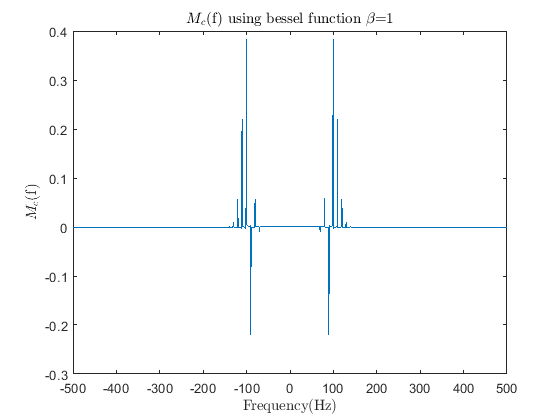

N2 = 5;
mc2_bessel_t = zeros(1,length(t));
for i = -N2:N2
    mc2_bessel_t = mc2_bessel_t + Ac*besselj(i,beta2)*cos(2*pi*(fc+i*f_m)*t); 
end
mc2_bessel_f = fftshift(fft(mc2_bessel_t))/length(mc2_bessel_t);
plot(f,real(mc2_bessel_f));
xlim([-500 500]);
title('$M_c$(f) using bessel function $\beta$=1','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');


$$\beta =10:$$


Jn10 = besselj(n,beta3);
for i = n
    if (i == 0)
        fprintf('Jn for Beta=10 (0<n<25\n');
    end
    fprintf('n = %d : %.4f\n',i,Jn10(i+1));
end

Jn for Beta=10 (0<n<25


n = 0 : -0.2459
n = 1 : 0.0435
n = 2 : 0.2546
n = 3 : 0.0584
n = 4 : -0.2196
n = 5 : -0.2341
n = 6 : -0.0145
n = 7 : 0.2167
n = 8 : 0.3179
n = 9 : 0.2919
n = 10 : 0.2075
n = 11 : 0.1231
n = 12 : 0.0634
n = 13 : 0.0290
n = 14 : 0.0120
n = 15 : 0.0045
n = 16 : 0.0016
n = 17 : 0.0005
n = 18 : 0.0002
n = 19 : 0.0000
n = 20 : 0.0000
n = 21 : 0.0000
n = 22 : 0.0000
n = 23 : 0.0000
n = 24 : 0.0000
n = 25 : 0.0000


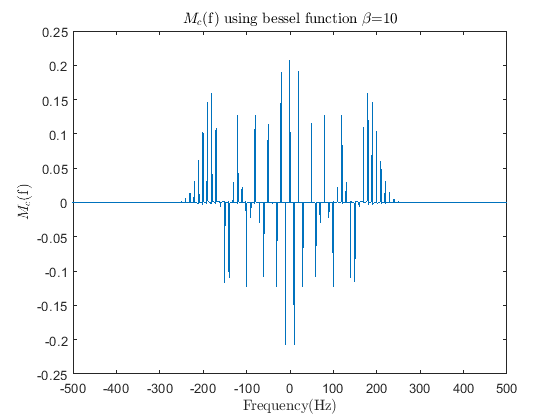

N3 = 18;
mc3_bessel_t = zeros(1,length(t));
for i = -N3:N3
    mc3_bessel_t = mc3_bessel_t + Ac*besselj(i,beta3)*cos(2*pi*(fc+i*f_m)*t); 
end
mc3_bessel_f = fftshift(fft(mc3_bessel_t))/length(mc3_bessel_t);
plot(f,real(mc3_bessel_f));
xlim([-500 500]);
title('$M_c$(f) using bessel function $\beta$=10','Interpreter','latex');
xlabel('Frequency(Hz)','Interpreter','latex');
ylabel('$M_c$(f)','Interpreter','latex');

# `Functions:`

`Function for PM Modulation:`

function [xc] = pm (xm,Ac,phasedev,fc,t)
    phi = phasedev*xm;
    xc = Ac*cos(2*pi*fc*t + phi);
end

`Function for NBPM Modulation:`

function [xc] = nbpm (xm,Ac,phasedev,fc,t)
    phi = phasedev*xm;
    xc = Ac*cos(2*pi*fc*t) - Ac*phi.*sin(2*pi*fc*t);
end

`Function for FM Modulation:`

function [xc] = fm (xm,Ac,freqdev,fc,t)
    xc = pm(cumtrapz(t,xm),Ac,2*pi*freqdev,fc,t);
%     phi = 2*pi*freqdev*cumtrapz(t,xm);
%     xc = Ac*cos(2*pi*fc*t + phi);
end

`Function for NBFM Modulation:`

function [xc] = nbfm (xm,Ac,freqdev,fc,t)
    xc = nbpm(cumtrapz(t,xm),Ac,2*pi*freqdev,fc,t);
%     phi = 2*pi*freqdev*cumtrapz(t,xm);
%     xc = Ac*cos(2*pi*fc*t) - Ac*phi.*sin(2*pi*fc*t);
end

`Function for FM Demodulation:`

function [xm] = fdm (xc,Ac,freqdev,fc,fs)
    dxc = fs * (xc - [xc(1) xc(1:length(xc)-1)]);
    env = envelope(dxc);
    xm = (env-Ac*2*pi*fc)/(Ac*2*pi*freqdev); 
end

`Function for PM Demodulation:`

function [xm] = pdm (xc,Ac,phasedev,fc,fs,t)
    dxm = fdm (xc,Ac,phasedev/(2*pi),fc,fs);
    xm = cumtrapz(t,dxm);
end